clc; clear; close; clf;


PE_d = [0.3; 0.5];
theta_initial = [pi/2; 2*pi];
threshold = 1e-10;


[theta] = IK_MinCoordinate(PE_d, theta_initial, threshold);
vpa(theta, 4)

$$ans = \left(\begin{array}{c} 1.268\\ 5.807 \end{array}\right)$$

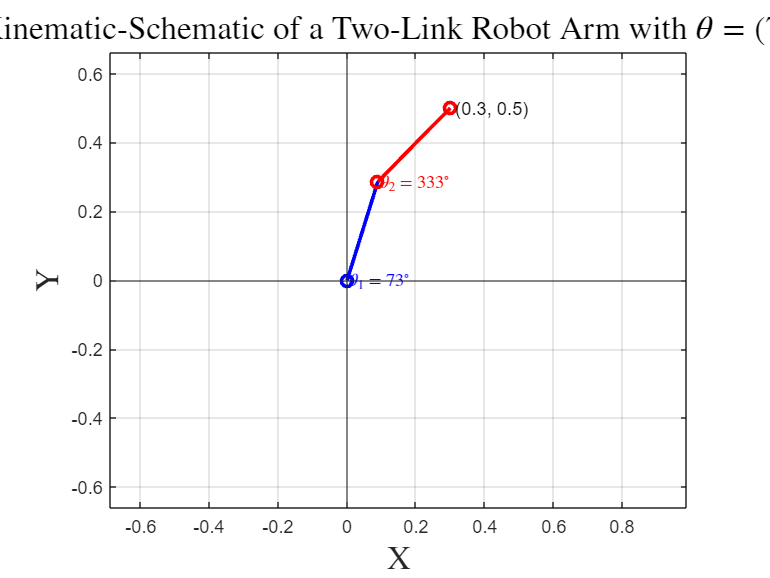


[X_E, Y_E] = FK_2R_Plot(theta(1), theta(2));

vpa([X_E; Y_E], 4)

$$ans = \left(\begin{array}{c} 0.3\\ 0.5 \end{array}\right)$$

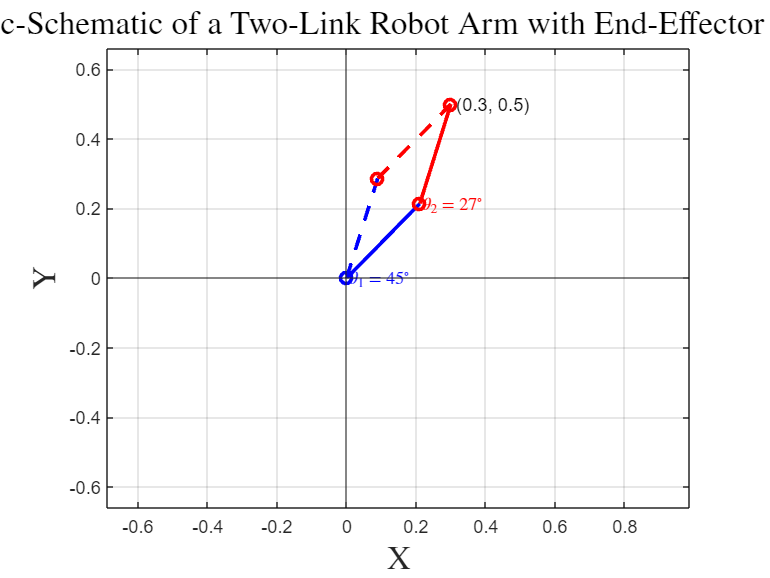

[theta1, theta2] = IK_2R(PE_d);

vpa(theta1, 4)

$$ans = \left(\begin{array}{c} 0.7924\\ 0.4759 \end{array}\right)$$

vpa(theta2, 4)

$$ans = \left(\begin{array}{c} 1.268\\ 5.807 \end{array}\right)$$

[thetas] = IK_AllSolutions(PE_d, threshold);
vpa(thetas, 4)

$$ans = \left(\begin{array}{cc} 0.7924 & 1.268\\ 0.4759 & 5.807 \end{array}\right)$$

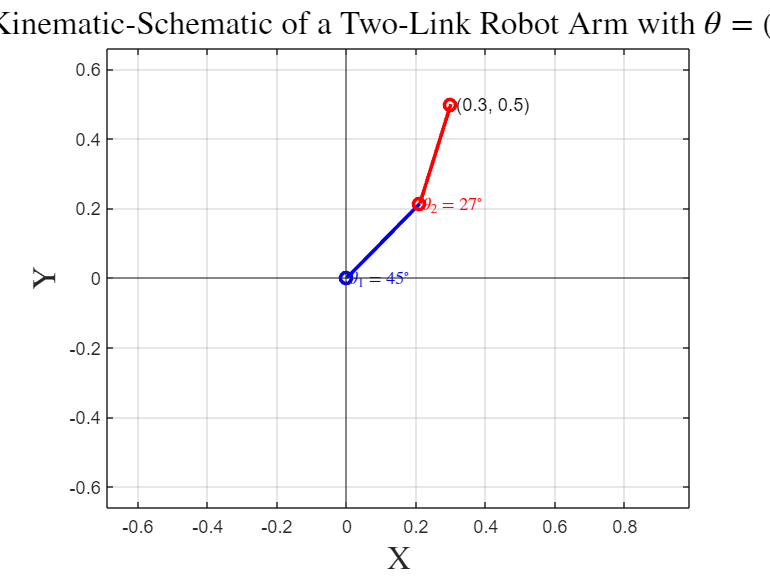

X_E = 0.3000

Y_E = 0.5000

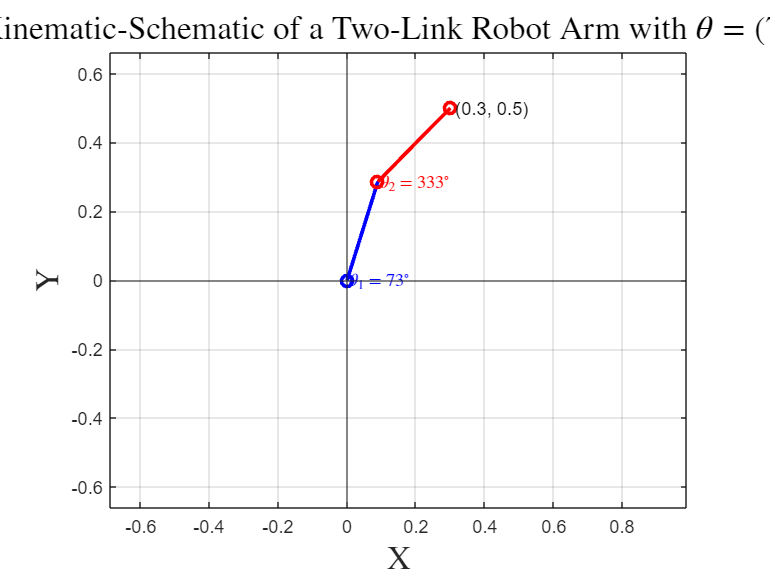

X_E = 0.3000

Y_E = 0.5000

for j = 1:size(thetas, 2)
    % Extract the jth column
    theta_j = thetas(:, j);
    [X_E, Y_E] = FK_2R_Plot(theta_j(1), theta_j(2))
end

clc
clear

S = [[0; 0; 1;0; 0; 0],[0; 0; 1; 0; -0.3; 0]];
theta = [pi/4; pi/6];
Js = J_SpaceForm(S, theta)

Js =          0         0
         0         0
    1.0000    1.0000
         0    0.2121
         0   -0.2121
         0         0



B = [[0; 0; 1; 0; 0.6; 0],[0; 0; 0; 0; 0.3; 0]];
Jb = J_BodyForm(B, theta)

Jb =          0         0
         0         0
    1.0000         0
   -0.1571         0
    0.6000    0.3000
         0         0



[x,y] = FK_2R (theta(1),theta(2));
p = [x,y,0];
p = VecToso3(p);
J_g = [eye(3) zeros(3);
       -p     eye(3)] * Js

J_g =          0         0
         0         0
    1.0000    1.0000
   -0.5019   -0.2898
    0.2898    0.0776
         0         0


[J] = J_2R (theta(1),theta(2))

J =    -0.5019   -0.2898
    0.2898    0.0776
